% define superclusters based on the clustering results
% Author: Chang Lu
% luchang4104@gmail.com

clear all

% you can put your data folder under 'data' 
currentFolder = pwd;

% datapath = [currentFolder,filesep,'data',filesep,'mix with cd163'];
% or set you own path( replace the sentence above to the example below):
% datapath = '/Users/changlu/DATA/OLIVIA/30 clusters CDK5 New'; % your own data path
datapath = '/Users/changlu/DATA/Elias/data';

addpath(genpath('fun'));
directory = [datapath,filesep,'results',filesep];
if ~exist(directory,'dir')
    mkdir(directory);
end

files=dir(fullfile(datapath));
isub = [files(:).isdir];
fileNames={files(isub).name}';
fileNames(ismember(fileNames,{'.','..','results'})) = [];


##  load data

%check the mat files in the datapath
load([datapath,filesep, 'cosine_kmedoids_k=30']); % clustering results
load([datapath,filesep, 'cellmarker_rescale_intergration_t=2']);

%h = draw_mst_new(labels,centers,'cosine',[],'T');
% print(gcf,'-dpng',[directory,'MST.jpg']);

## define super clusters by yourself

SC-1: 1+21+22+18

SC-2: 9+29 

SC-3: 7+10

SC-4: 15+24+2 

SC-5: 12+3+8

SC-6: 20+4+16+6

SC-7: 28+5+27

SC-8: 13+14+19+23+26 

superlabels = insertBefore(string(labels),1,"SC-");
superlabels(labels == 1 | labels == 21 | labels == 22 | labels == 18) = "SC-1";
superlabels(labels == 9 | labels == 29) = "SC-2";
superlabels(labels == 7 | labels == 10) = "SC-3";
superlabels(labels == 15 | labels == 24 | labels == 2) = "SC-4";
superlabels(labels == 12 | labels == 3 | labels == 8) = "SC-5";
superlabels(labels == 20 | labels == 4 | labels == 16 | labels == 6) = "SC-6";
superlabels(labels == 28 | labels == 5 | labels == 27) = "SC-7";
superlabels(labels == 13| labels == 23| labels == 26| labels == 19| labels == 14) = "SC-8";

## define super clusters

SC1: 9, 28, 10, 15

SC2: 19, 8, 7 , 29

SC3: 21, 2, 12

SC4: 11, 22, 5, 27, 3

SC5: 14, 25

SC6: 1, 6, 16

SC7: 26, 29


superlabels = insertBefore(string(labels),1,"SC-");
superlabels(labels == 9 | labels == 10 | labels == 28 | labels == 15) = "SC-1";
superlabels(labels == 7 | labels == 8 | labels == 19 | labels == 29) = "SC-2";
superlabels(labels == 2 | labels == 12 | labels == 21) = "SC-3";
superlabels(labels == 3 | labels == 5 | labels == 11 | labels == 22| labels == 27) = "SC-4";
superlabels(labels == 14 | labels == 25 ) = "SC-5";
superlabels(labels == 1 | labels == 6 | labels == 16) = "SC-6";
superlabels(labels == 26 | labels == 29) = "SC-7";


%supercolors = flipud(jet(length(unique(superlabels))));
supercolors = [1 1 0; 
    1 0 1; 
    0 1 1;
    1 0 0;
    0 1 0;
    0 0 1; 
    0 0 0; 
    1 0.5 0.3; 
    1 0 0.5; 
    0 0.5 1; 
    0.5 0.8 0; 
    0.7 0.2 0.5; 
    0.5 0 0.5;
    0.2 1 0.2];
uni_labels = unique(unique(superlabels));
COLORT = table(supercolors(1:length(uni_labels),:),uni_labels);
COLORT.Properties.VariableNames{'uni_labels'} = 'superlabels';
COLORT.Properties.VariableNames{'Var1'} = 'supercolors';
bindtable = unique(table(labels, superlabels),'rows');
TT = join(bindtable,COLORT,'Keys','superlabels');
writetable(TT,[datapath,filesep, 'rescale_t=3_supercluster.csv'])

## visualization: MST

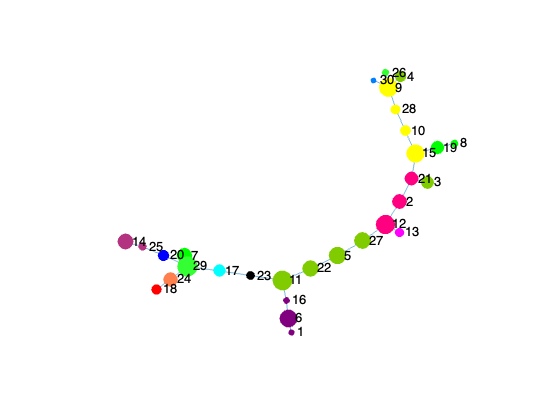

h = draw_mst_new(labels,centers,'cosine',TT.supercolors, 'F');
print(gcf,'-dpng',[directory,'SuperClu-MST.jpg']);